%% Parameters
J  = 3e-2;      % inertia [kg*m^2]
Cw = 0.01;      % rotational damping [N*m*s/rad]
Ts = 0.005;     % sample time [s] (2 ms)

s = tf('s');

%% Continuous inner plant: M -> w   ( w_dot = (-Cw*w + M)/J )
G_inner_c = 1/(J*s + Cw);

%% Discretize inner plant and outer integrator
G_inner = c2d(G_inner_c, Ts, 'zoh');       % M -> w (discrete)
G_phi   = c2d(1/s,         Ts, 'tustin');  % w -> phi (discrete integrator)

%% Tunable discrete PIDs (fixed Ts)
C_inner = tunablePID('C_inner','PID');  C_inner.Ts = Ts;  % rate PID
C_outer = tunablePID('C_outer','PID');  C_outer.Ts = Ts;  % angle PID

% Constraints
C_inner.Kp.Minimum = 0;
C_inner.Ki.Minimum = 0;
C_inner.Kd.Minimum = 0;


%% Name I/Os for interconnection
C_outer.InputName = 'e_phi';   C_outer.OutputName = 'w_ref';
C_inner.InputName = 'e_w';     C_inner.OutputName = 'M';
G_inner.InputName = 'M';       G_inner.OutputName = 'w';
G_phi.InputName   = 'w';       G_phi.OutputName   = 'phi';

%% Summing junctions
Sum_w   = sumblk('e_w  = w_ref - w');
Sum_phi = sumblk('e_phi = phi_ref - phi');

%% Generalized closed-loop (phi_ref -> phi)
% Expose 'e_w' and 'e_phi' as analysis points for margins
CL0 = connect(C_outer, C_inner, G_inner, G_phi, ...
              Sum_w, Sum_phi, ...
              'phi_ref','phi', ...
              {'e_w','e_phi'});

%% Tuning goals
ReqTrack = TuningGoal.Tracking('phi_ref','phi',1);   % track angle reference
ReqMi    = TuningGoal.Margins('e_w',6,45);           % inner loop robustness
ReqMo    = TuningGoal.Margins('e_phi',6,45);         % outer loop robustness

[CLtuned,fSoft] = systune(CL0,[ReqTrack,ReqMi,ReqMo]);

Final: Soft = 1.01, Hard = -Inf, Iterations = 62
       Some closed-loop poles are marginally stable (decay rate near 1e-07)



%% Show tuned PID gains
showTunable(CLtuned)

C_inner =
 
              Ts               1     
  Kp + Ki * ------ + Kd * -----------
              z-1         Tf+Ts/(z-1)

  with Kp = 0.23, Ki = 0.097, Kd = 0.305, Tf = 0.0661, Ts = 0.005
 
Name: C_inner
Sample time: 0.005 seconds
Discrete-time PIDF controller in parallel form.
-----------------------------------
C_outer =
 
              Ts               1     
  Kp + Ki * ------ + Kd * -----------
              z-1         Tf+Ts/(z-1)

  with Kp = 1.99, Ki = 3.98e-05, Kd = 0.456, Tf = 2.38, Ts = 0.005
 
Name: C_outer
Sample time: 0.005 seconds
Discrete-time PIDF controller in parallel form.


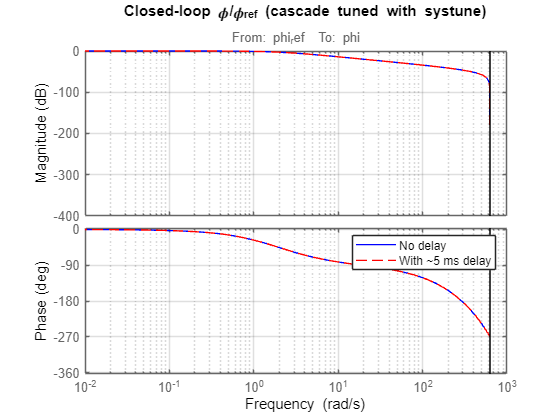


%% Closed-loop (no delay) transfer phi/phi_ref for plotting
T_noDelay = getIOTransfer(CLtuned,'phi_ref','phi');

%% Add ~5 ms delay in the angle measurement path (discrete N-sample delay)
Td     = 0.005;                    % 5 ms
Ndelay = max(1, round(Td/Ts));     % integer samples (5ms @ 2ms -> 3 samples)
DelayN = tf([zeros(1,Ndelay) 1], 1, Ts);  % z^(-N)

% Replace G_phi by Delay * G_phi and reconnect using tuned controllers
Ki = getBlockValue(CLtuned,'C_inner');  % numeric discrete PID
Ko = getBlockValue(CLtuned,'C_outer');
% Ki.InputName = 'e_w';    Ki.OutputName = 'M';
% Ko.InputName = 'e_phi';  Ko.OutputName = 'w_ref';

Ki.InputName = 'e_w';    Ki.OutputName = 'M';
Ko.InputName = 'e_phi';  Ko.OutputName = 'w_ref';


G_phi_d = series(DelayN, G_phi);

G_phi_d.InputName = 'w';
G_phi_d.OutputName = 'phi';


CL_delay = connect(Ko, Ki, G_inner, G_phi_d, Sum_w, Sum_phi, ...
                   'phi_ref','phi');
T_delay  = zpk(CL_delay);

%% Bode comparison (closed-loop angle response)
figure; bode(T_noDelay,'b', T_delay,'r--'); grid on;
legend('No delay','With ~5 ms delay');
title('Closed-loop \phi/\phi_{ref} (cascade tuned with systune)');

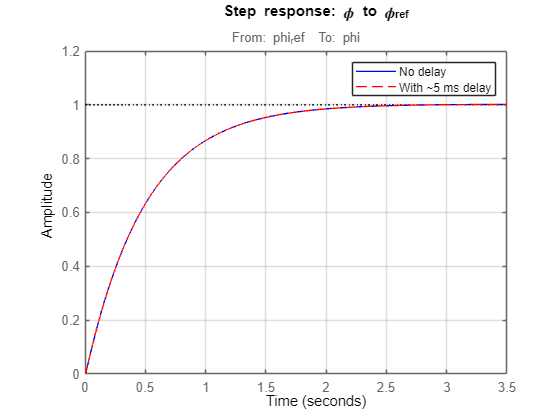


%% Step responses for intuition
figure; step(T_noDelay,'b', T_delay,'r--'); grid on;
legend('No delay','With ~5 ms delay');
title('Step response: \phi to \phi_{ref}');